#  MAIN_SIM_1D_PARAMSWP_PROC

 This script examines the effect of parameter choices through simulation. The results are stored in folder "./results" as follows:

 /results/sweepparams1d-yyyy-MM-dd-HH-mm.mat

-  tables: 'tbPropPds','tbPropAdmm','tbRef1dtv'

-  cells:  'configs_proppds','configs_propadmm','configs_ref1dtv'

 Requirements: MATLAB R2022a

 Copyright (c) 2022, Ruiki KOBAYASHI and Shogo MURAMATSU

 All rights reserved.

 Contact address: Shogo MURAMATSU,

    Faculty of Engineering, Niigata University,

    8050 2-no-cho Ikarashi, Nishi-ku,

    Niigata, 950-2181, JAPAN

     http://msiplab.eng.niigata-u.ac.jp/

rng(0) % Initialize random generator
close all % Close figures
mymse = @(x,y) mean((x(:)-y(:)).^2); % MSE
isVisible = true;

## Fixed configurations

nTrials = 10; % # of trials
nIters = 1000; % # of iterations
nSamples = 256; % # of samples
vrange  = [1.0 1.5]; % Range of reflactive index

## For measurement process P

msrparams.alpha_p = 1.0; % Amplitude
msrparams.omega_p = 0.3*pi; % Frequency of fluctuation
msrparams.sigma_z = 30; % Standard deviation of Gaussian function
msrparams.b_p = 0.05; % Broadening paramete

## Variable parameters for sweep

sigmaws = (1:5)*1e-2;           % Standard deviation of AWGN
levelSet = (1:5);               % Tree level of dictionary
etaSet = logspace(-1.6,-0.6,16);    % Reg. Param. for proposed/reference model
lambdaSet = logspace(-3.8,-0.8,16); % Reg. Param. for proposed model
rhoSet = logspace(-2,-1.6,3);   % Reg. Param. for proposed model w/ ADMM

## Original sequence

u = fcn_rigen1d_(nSamples,vrange);

## Reflection model

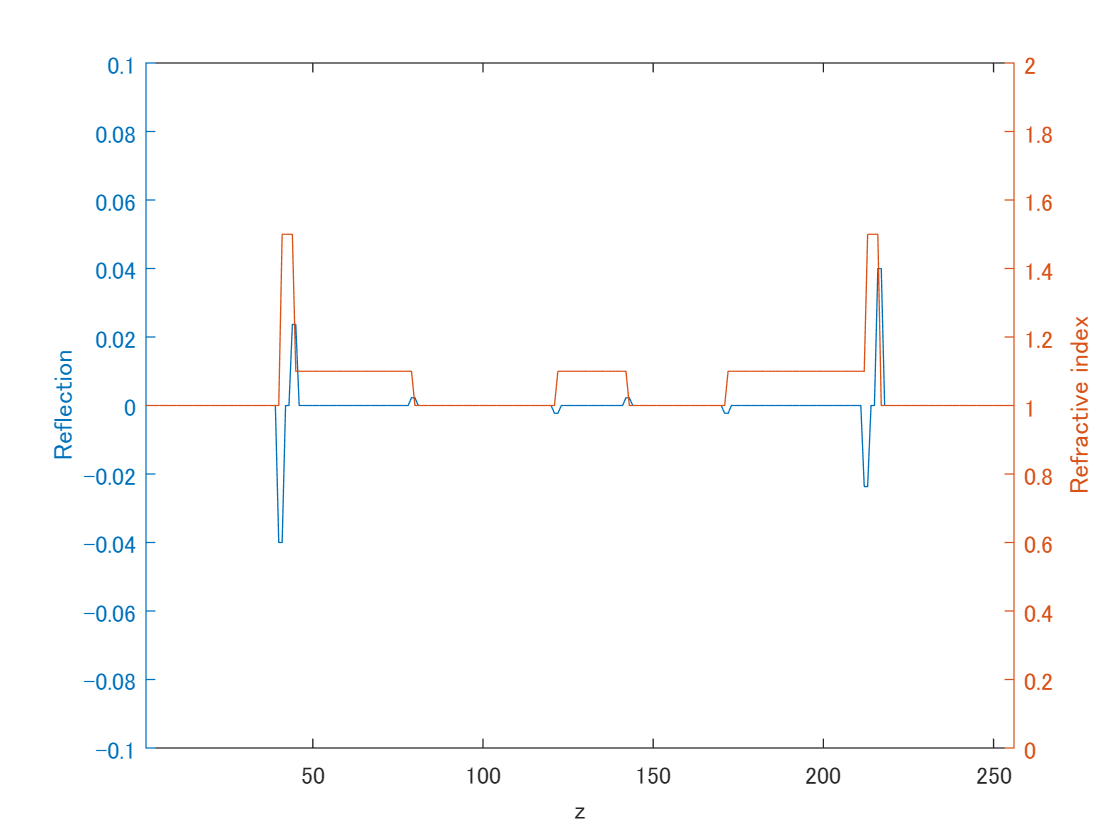

r = fcn_phi1d_(u,'reflection');

% Graph plot
if isVisible
    figure
    plotur_(u, r, nSamples);
end

## Measurement process

[measureproc, measureadjp] = fcn_gencoh1d_(nSamples,msrparams);

## Evaluation

if isVisible
    figure
end

% Configurations for all approaches
configcom_.nIters = nIters;
configcom_.measurement = {measureproc, measureadjp};

% Configurations for proposed methods
configprop_ = configcom_;
configprop_.vrange = vrange;

## Configurations for proposed method w/ PDS

config_ = configprop_;
% Prepare configurations for PDS
nConfigs_ = length(levelSet)*length(etaSet)*length(lambdaSet);
configs_proppds = cell(nConfigs_,1);
iConfig = 1;
for iLevel = levelSet
    % Dictionaries
    analyzer = @(x) udhaardec_(x,iLevel);
    synthesizer = @(y) udhaarrec_(y,iLevel);
    config_.nLevels = iLevel;
    config_.dictionaries = {analyzer,synthesizer};
    % Eta
    for eta_ = etaSet
        config_.eta = eta_;
        % Lambda
        for lambda_ = lambdaSet
            config_.lambda = lambda_;
            % Set configulation
            configs_proppds{iConfig} = config_;
            iConfig = iConfig + 1;
        end
    end
end

## Configurations for proposed method w/ ADMM

config_ = configprop_;
% Prepare configurations for ADMM
nConfigs_ = length(levelSet)*length(etaSet)*length(lambdaSet)*length(rhoSet);
configs_propadmm = cell(nConfigs_,1);
iConfig = 1;
for iLevel = levelSet
    % Dictionaries
    analyzer = @(x) udhaardec_(x,iLevel);
    synthesizer = @(y) udhaarrec_(y,iLevel);
    config_.nLevels = iLevel;    
    config_.dictionaries = {analyzer,synthesizer};
    % Eta
    for eta_ = etaSet
        config_.eta = eta_;
        % Lambda
        for lambda_ = lambdaSet
            config_.lambda = lambda_;
            for rho_ = rhoSet
                config_.rho = rho_;
                % Set configulation
                configs_propadmm{iConfig} = config_;
                iConfig = iConfig + 1;
            end
        end
    end
end

## Configurations for reference 1DTV method w/ PDS

config_ = configcom_;
% Prepare configurations
nConfigs_ = length(etaSet);
configs_ref1dtv = cell(nConfigs_,1);
iConfig = 1;
% Eta
for eta_ = etaSet
    config_.eta = eta_;
    % Set configulation
    configs_ref1dtv{iConfig} = config_;
    iConfig = iConfig + 1;
end

## Prepare tables

varNamesPropPds_ = {'iConfig','mse','sigmaw','iTrial','nLevels','eta','lambda','mu','gamma1','gamma2'};
tbPropPds = table('Size',[0,10],...
    'VariableTypes',...
    {'uint64','double','double','uint32','uint32','double','double','double','double','double',},...
    'VariableNames',varNamesPropPds_);
varNamesPropAdmm_ = {'iConfig','mse','sigmaw','iTrial','nLevels','eta','lambda','rho'};
tbPropAdmm = table('Size',[0,8],...
    'VariableTypes',...
    {'uint64','double','double','uint32','uint32','double','double','double'},...
    'VariableNames',varNamesPropAdmm_);
varNamesRef1dtv_ = {'iConfig','mse','sigmaw','iTrial','eta','mu','gamma1','gamma2'};
tbRef1dtv = table('Size',[0,8],...
    'VariableTypes',...
    {'uint64','double','double','uint32','double','double','double','double'},...
    'VariableNames',varNamesRef1dtv_);

## Evaluation

for sigmaw = sigmaws
    disp(['sigmaw: ' num2str(sigmaw)])
    for iTrial = 1:nTrials
        disp([' #trial: ' num2str(iTrial)])
        % Noise
        w = sigmaw*randn(size(r));
        % Observation
        v = measureproc(r) + w;

        % Graph plot
        if isVisible
            ploturv_(u,r,v,nSamples)
            title(['Observation v (\sigma_w = ' num2str(sigmaw) ')'])
            drawnow
        end

sigmaw: 0.01


 #trial: 1


## Proposal w/ PDS

        nConfigs_ = length(configs_proppds);
        rowsPropPds_ = cell(nConfigs_,1);
        tic
        parfor iConfig=1:nConfigs_
            config_ = configs_proppds{iConfig};
            [rhat_,mu,gammas] = support.fcn_proppds1d(v,config_);
            mse_ = mymse(r,rhat_);
            eta = config_.eta;
            lambda = config_.lambda;
            level = config_.nLevels;
            rowsPropPds_{iConfig} = { ...
                iConfig,mse_,sigmaw,iTrial,level,eta,lambda,mu,gammas(1),gammas(2) };
        end
        tbTmp_ = cellfun(@(x) cell2table(x,'VariableNames',varNamesPropPds_),...
            rowsPropPds_,'UniformOutput',false);
        for iConfig=1:nConfigs_
            tbPropPds = [tbPropPds;tbTmp_{iConfig}]; %#ok<AGROW> 
        end
        disp(' Finished Proposal w/ PDS')
        toc

## Proposal w/ ADMM

        nConfigs_ = length(configs_propadmm);
        rowsPropAdmm_ = cell(nConfigs_,1);
        tic
        parfor iConfig=1:nConfigs_
            config_ = configs_propadmm{iConfig};
            rhat_ = nan(size(v));
            try
                rhat_ = support.fcn_propadmm1d(v,config_);
            catch ME
                warning([ME.message ' (rho: ' num2str(config_.rho) ')'])
            end
            mse_ = mymse(r,rhat_);
            eta = config_.eta;
            lambda = config_.lambda;
            rho = config_.rho;
            level = config_.nLevels;
            rowsPropAdmm_{iConfig} = { ...
                iConfig,mse_,sigmaw,iTrial,level,eta,lambda,rho };
        end
        tbTmp_ = cellfun(@(x) cell2table(x,'VariableNames',varNamesPropAdmm_),...
            rowsPropAdmm_,'UniformOutput',false);
        for iConfig=1:nConfigs_
            tbPropAdmm = [tbPropAdmm;tbTmp_{iConfig}]; %#ok<AGROW> 
        end
        disp(' Finished Proposal w/ ADMM')
        toc

## Reference method w/ PDS

        nConfigs_ = length(configs_ref1dtv);
        rowsRef1dtv_ = cell(nConfigs_,1);
        tic
        parfor iConfig=1:nConfigs_
            config_ = configs_ref1dtv{iConfig};
            [rhat_,mu,gammas] = support.fcn_refpds1dtv(v,config_);
            mse_ = mymse(r,rhat_);
            eta = config_.eta;
            rowsRef1dtv_{iConfig} = { ...
                iConfig,mse_,sigmaw,iTrial,eta,mu,gammas(1),gammas(2)};
        end
        tbTmp_ = cellfun(@(x) cell2table(x,'VariableNames',varNamesRef1dtv_),...
            rowsRef1dtv_,'UniformOutput',false);
        for iConfig=1:nConfigs_
            tbRef1dtv = [tbRef1dtv;tbTmp_{iConfig}]; %#ok<AGROW> 
        end
        disp(' Finished Reference w/ PDS')
        toc

    end
end

## Store results

t = char(datetime('now','Format','yyyy-MM-dd-HH-mm'));
save(['./results/sweepparams1d-' t],...
    'tbPropPds','tbPropAdmm','tbRef1dtv',...
    'configs_proppds','configs_propadmm','configs_ref1dtv',...
    'msrparams');

## Local functions

%---

function y = fcn_phi1d_(u,mode,ribound)
%FCN_PHI1D Function to convert refractive index to reflection
%
dz = [1 0 -1];
az = [1 0  1];
dzu = circshift(cconv(dz,u,length(u)),-1);
azu = circshift(cconv(az,u,length(u)),-1);
if nargin < 3
    ribound = [1.0 1.5];
end
if strcmp(mode,'reflection')
    y = abs(dzu).*(-dzu)./(azu.^2);
elseif strcmp(mode,'linear')
    b = ribound(2);
    a = ribound(1);
    y = -beta1(a,b)*dzu;
else
    error('Not supported')
end
end

%---
function [measureproc,measureadjp] = fcn_gencoh1d_(nSamples,params)
%FCN_GENCOH1D Generation of measurement process
alpha_p = params.alpha_p; % Amplitude
omega_p = params.omega_p; % Frequency of fluctuation
sigma_z = params.sigma_z; % Standard deviation of Gaussian function
b_p = params.b_p; % Broadening parameter

% Impluse response of measurement process
p = @(m) alpha_p.*exp(-m.^2/(2*sigma_z.^2)).*cos(omega_p*m).*sinc(b_p*m);
% Impulse response of P
hlen = round(3*sigma_z);
zsmpl = -hlen:hlen;
irp = p(zsmpl); % impluse response of p

% Measurement process
measureproc = @(x) circshift(cconv(irp,x,nSamples),-floor(length(irp)/2));
measureadjp = @(x) circshift(cconv(irp(end:-1:1),x,nSamples),mod(length(irp)-1,2)-floor(length(irp)/2));

% Check if <Px,y> = <x,P.'y> (is adjoint?)
fcn_isinadjrel_(measureproc,measureadjp,nSamples)
end

%---
function fcn_isinadjrel_(fwdp,adjp,nSamples1,nSamples2)
%FCN_ISINADJREL Function to check the adjoint relationship
%
if nargin < 4
    nSamples2 = nSamples1;
end
x1 = randn(nSamples1,1);
y1 = fwdp(x1);
y2 = randn(nSamples2,1);
x2 = adjp(y2);
err = abs(x1(:).'*x2(:)-y1(:).'*y2(:));
assert(err<1e-9,'Adjoint relation is not met. (abs err: %f)',err)
end

%---
function u = fcn_rigen1d_(nSamples,vrange)
%FCN_RIGEN1D Generation of refractive index distribution
% Generation of a refractive index distribution for simulation
u2d = phantom('Modified Shepp-Logan',nSamples);
minu2d = min(u2d(:));
maxu2d = max(u2d(:));
ri_lb = vrange(1);
ri_ub = vrange(2);
u2d = (ri_ub-ri_lb)*(u2d-minu2d)/(maxu2d-minu2d)+ri_lb; % Normalize to [a,b]
% Extraction of 1-D sequence
u = u2d(floor(end/2),:);
end

%---
function plotur_(u, r, nSamples)
yyaxis right
plot(u)
ylabel('Refractive index')
xlabel('z')
axis([1 nSamples 0 2])
yyaxis left
plot(r)
ylabel('Reflection')
axis([1 nSamples -0.1 0.1])
end

%---
function ploturv_(u, r, v, nSamples)
subplot(3,1,1)
plot(u)
title('Refractive index {\bf u}')
xlabel('z')
axis([1 nSamples 0 2])
subplot(3,1,2)
plot(r)
title('Refletion {\bf r}')
xlabel('z')
axis([1 nSamples -0.1 0.1])
subplot(3,1,3)
plot(v)
title('Observation {\bf v}')
xlabel('z')
axis([1 nSamples -0.2 0.2])
hold off
end

%---
% Undecimated Haar decomposition
function y = udhaardec_(x,nLevels)
    swc = swtscale_(nLevels)*swt(x,nLevels,'haar');
    y = swc(:);
end

% Undecimated Haar reconstruction
function x = udhaarrec_(y,nLevels)
    swc = swtscale_(nLevels)\reshape(y,nLevels+1,[]);
    x = iswt(swc,'haar');
end

% Scaling factor for Parseval tight property 
function s = swtscale_(nLevels)
    s = diag([2.^(-(1:nLevels)/2) 2^(-nLevels/2)]);
end